# 机身运动学动力学建模

## 1 坐标系建立

为了便于计算，我们直接将机身坐标系设定为与世界坐标系姿态相同，原点位于机身几何中心的坐标系。

世界坐标系原点被设置于初始时刻机体坐标系 y 轴的轴线上，与地面同高。

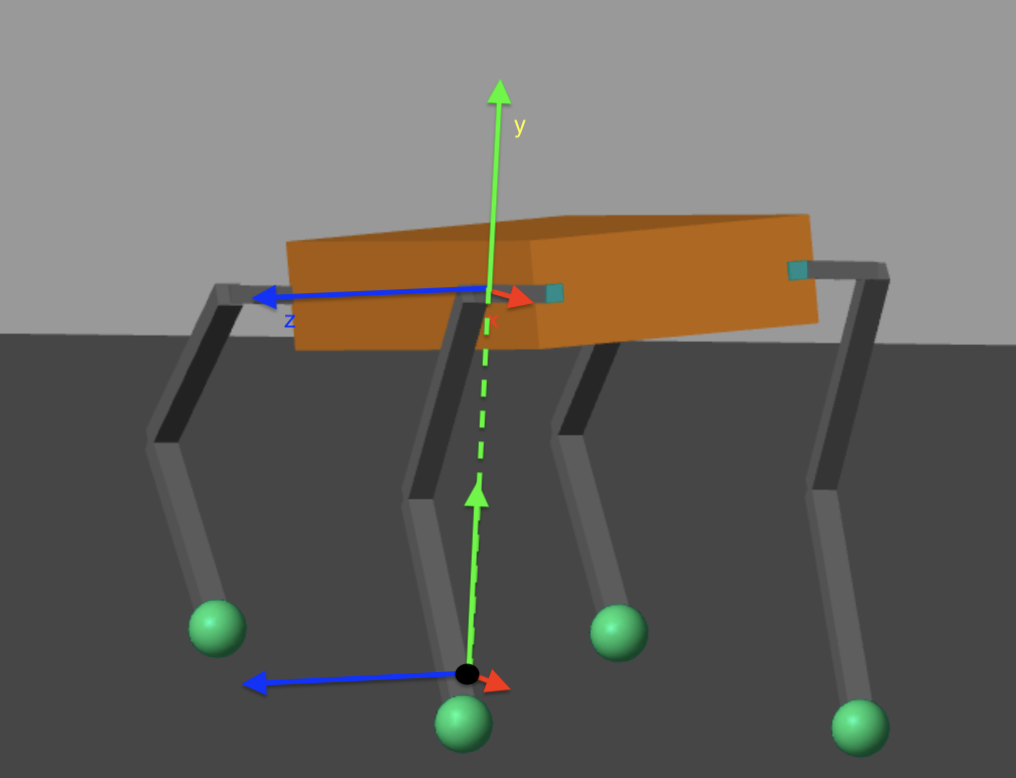

## 2 参数定义

$R_{sb}$: 机身相对于世界坐标系的旋转矩阵

$f_{i,i = RR,RF,LR,LF}$:地面分别对四条腿的作用力

$\bf{p}$ $= [x,y,z]$: 机身相对于世界坐标系的位置

$\bf{\omega}$ $= [\omega_x, \omega_y, \omega_z]$: 机身相对于世界坐标系的姿态

$I_b
$: 机体的惯性张量

$m$: 机身质量

$P_{i \times, i = RR,RF,LR,LF}$: $[P_i]_{\times}$ 机体坐标系原点到足端的位置向量与其他向量做向量积的结果

Body = struct;

g = sym("g");

Body.m = sym("m");
Body.fRR = sym("fRR");
Body.fRF = sym("fRF");
Body.fLR = sym("fLR");
Body.fLF = sym("fLF");
Body.x = sym("x");
Body.y = sym("y");
Body.z = sym("z");
Body.p = [Body.x;Body.y;Body.z];
Body.wx = sym("wx");
Body.wy = sym("wy");
Body.wz = sym("wz");
Body.x = [Body.wx;Body.wy;Body.wz];
Body.Rsb = "Rsb";
Body.Ib = "Ib";
Body.PRRx = "PRRx";
Body.PRFx = "PRFx";
Body.PLRx = "PLRx";
Body.PLFx = "PLFx";

Body.z33 = "zeros(3,3)";
Body.z31 = "zeros(3,1)";
Body.z13 = "zeros(1,3)";
Body.eye3 = "eye(3)";
Body.g3 = "[0;-1;0]";

% Body.Rsb1 = sym("Ib1");
% Body.Rsb2 = sym("Rsb2");
% Body.Rsb3 = sym("Rsb3");
% Body.Rsb4 = sym("Rsb4");
% Body.Rsb5 = sym("Rsb5");
% Body.Rsb6 = sym("Rsb6");
% Body.Rsb7 = sym("Rsb7");
% Body.Rsb8 = sym("Rsb8");
% Body.Rsb9 = sym("Rsb9");
% Body.Rsb = [Body.Rsb1,Body.Rsb4,Body.Rsb7;
%             Body.Rsb2,Body.Rsb5,Body.Rsb8;
%             Body.Rsb3,Body.Rsb6,Body.Rsb9;];
% 
% Body.Ib1 = sym("Ib1");
% Body.Ib2 = sym("Ib2");
% Body.Ib3 = sym("Ib3");
% Body.Ib4 = sym("Ib4");
% Body.Ib5 = sym("Ib5");
% Body.Ib6 = sym("Ib6");
% Body.Ib7 = sym("Ib7");
% Body.Ib8 = sym("Ib8");
% Body.Ib9 = sym("Ib9");
% Body.Ib = [Body.Ib1,Body.Ib4,Body.Ib7;
%             Body.Ib2,Body.Ib5,Body.Ib8;
%             Body.Ib3,Body.Ib6,Body.Ib9;];
% 
% Body.PRRx1 = sym("PRRx1");
% Body.PRRx2 = sym("PRRx2");
% Body.PRRx3 = sym("PRRx3");
% Body.PRRx4 = sym("PRRx4");
% Body.PRRx5 = sym("PRRx5");
% Body.PRRx6 = sym("PRRx6");
% Body.PRRx7 = sym("PRRx7");
% Body.PRRx8 = sym("PRRx8");
% Body.PRRx9 = sym("PRRx9");
% Body.PRRx = [Body.PRRx1,Body.PRRx4,Body.PRRx7;
%             Body.PRRx2,Body.PRRx5,Body.PRRx8;
%             Body.PRRx3,Body.PRRx6,Body.PRRx9;];
% 
% Body.PRFx1 = sym("PRFx1");
% Body.PRFx2 = sym("PRFx2");
% Body.PRFx3 = sym("PRFx3");
% Body.PRFx4 = sym("PRFx4");
% Body.PRFx5 = sym("PRFx5");
% Body.PRFx6 = sym("PRFx6");
% Body.PRFx7 = sym("PRFx7");
% Body.PRFx8 = sym("PRFx8");
% Body.PRFx9 = sym("PRFx9");
% Body.PRFx = [Body.PRRx1,Body.PRRx4,Body.PRRx7;
%             Body.PRRx2,Body.PRRx5,Body.PRRx8;
%             Body.PRRx3,Body.PRRx6,Body.PRRx9;];
% 
% Body.PLRx1 = sym("PLRx1");
% Body.PLRx2 = sym("PLRx2");
% Body.PLRx3 = sym("PLRx3");
% Body.PLRx4 = sym("PLRx4");
% Body.PLRx5 = sym("PLRx5");
% Body.PLRx6 = sym("PLRx6");
% Body.PLRx7 = sym("PLRx7");
% Body.PLRx8 = sym("PLRx8");
% Body.PLRx9 = sym("PLRx9");
% Body.PLRx = [Body.PLRx1,Body.PLRx4,Body.PLRx7;
%             Body.PLRx2,Body.PLRx5,Body.PLRx8;
%             Body.PLRx3,Body.PLRx6,Body.PLRx9;];
% 
% Body.PLFx1 = sym("PLFx1");
% Body.PLFx2 = sym("PLFx2");
% Body.PLFx3 = sym("PLFx3");
% Body.PLFx4 = sym("PLFx4");
% Body.PLFx5 = sym("PLFx5");
% Body.PLFx6 = sym("PLFx6");
% Body.PLFx7 = sym("PLFx7");
% Body.PLFx8 = sym("PLFx8");
% Body.PLFx9 = sym("PLFx9");
% Body.PLFx = [Body.PLFx1,Body.PLFx4,Body.PLFx7;
%             Body.PLFx2,Body.PLFx5,Body.PLFx8;
%             Body.PLFx3,Body.PLFx6,Body.PLFx9;];

## 3 运动学推导

该项目控制中不涉及机体运动学控制，需要示例可在 [运动学控制仿真](matlab:open('./WholeBody.slx')) 中找到。

% %% 因为不希望足端发生滑移，所以我们有已经固定的各个 p_{si}
% psRR = [0;0;0;1];
% psRF = [2.5;0;0;1];
% psLR = [0;0;-0.7;1];
% psLF = [2.5;0;-0.7;1];
% 
% %% 根据我们希望的机体目标状态，我们可以求解出世界坐标系到机体坐标系的齐次变换矩阵
% syms x y z alpha beta gamma
% 
% % 得出绕各个轴的旋转矩阵
% Rz = [cos(alpha) -sin(alpha) 0;
%       sin(alpha) cos(alpha) 0;
%       0 0 1];
% Ry = [cos(beta) 0 sin(beta);
%       0 1 0;
%       -sin(beta) 0 cos(beta)];
% Rx = [1 0 0;
%       0 cos(gamma) -sin(gamma);
%       0 sin(gamma) cos(gamma)];
% % 得出机体坐标系原点在世界坐标系中的坐标
% pbRR0 = [-1.25;-1;0.35+0.2];
% pd = [x;y;z];
% 
% Tsb = [Rz*Ry*Rx -pbRR0+pd;
%        zeros(1,3) ones(1,1)];
% 
% Tbs = [(Rz*Ry*Rx)' -(Rz*Ry*Rx)'*(-pbRR0+pd);
%         zeros(1,3) ones(1,1)];
% 
% %% 根据齐次变换矩阵，我们可以求解机体坐标系下的足端位置
% pbRR = Tbs * psRR;
% pbRF = Tbs * psRF;
% pbLR = Tbs * psLR;
% pbLF = Tbs * psLF;
% 
% % % 测试
% % x = 0;
% % y = 0;
% % z = 0;
% % alpha = 0;
% % beta = 0;
% % gamma = 0;
% % eval(pbLF)
% 
% %% 再求出单腿坐标系下的足端位置，用单腿逆运动学得到各个关节角度就可以了
% plRR = pbRR(1:3,:) - [-1.25;0;0.35];
% plRF = pbRF(1:3,:) - [1.25;0;0.35];
% plLR = pbLR(1:3,:) - [-1.25;0;-0.35];
% plLF = pbLF(1:3,:) - [1.25;0;-0.35];
% 
% % x = 0;
% % y = 0;
% % z = 0;
% % alpha = 0;
% % beta = 0;
% % gamma = 0;
% % eval(plRR)

## 4 动力学推导

推导动力学方程的必要性在于，我们需要利用它来写出机身的状态空间方程。所以以下只会给出状态空间方程的定义，需要动力学方程推导的可以在《四足机器人控制算法》中找到。

Body.A = strings(5,5);

Body.A(1,1) = Body.z33;
Body.A(1,2) = Body.eye3;
Body.A(1,3) = Body.z33;
Body.A(1,4) = Body.z33;
Body.A(1,5) = Body.z31;
Body.A(2,1) = Body.z33;
Body.A(2,2) = Body.z33;
Body.A(2,3) = Body.z33;
Body.A(2,4) = Body.z33;
Body.A(2,5) = Body.g3;
Body.A(3,1) = Body.z33;
Body.A(3,2) = Body.z33;
Body.A(3,3) = Body.z33;
Body.A(3,4) = Body.Rsb;
Body.A(3,5) = Body.z31;
Body.A(4,1) = Body.z33;
Body.A(4,2) = Body.z33;
Body.A(4,3) = Body.z33;
Body.A(4,4) = Body.z33;
Body.A(4,5) = Body.z13;
Body.A(5,1) = Body.z13;
Body.A(5,2) = Body.z13;
Body.A(5,3) = Body.z13;
Body.A(5,4) = Body.z13;
Body.A(5,5) = Body.z13;

Body.B = strings(5,4);

Body.B(1,1) = Body.z33;
Body.B(1,2) = Body.z33;
Body.B(1,3) = Body.z33;
Body.B(1,4) = Body.z33;
Body.B(2,1) = Body.eye3+'/m';
Body.B(2,2) = Body.eye3+'/m';
Body.B(2,3) = Body.eye3+'/m';
Body.B(2,4) = Body.eye3+'/m';
Body.B(3,1) = Body.z33;
Body.B(3,2) = Body.z33;
Body.B(3,3) = Body.z33;
Body.B(3,4) = Body.z33;
Body.B(4,1) = '('+Body.Rsb+'*'+Body.Ib+'*'+Body.Rsb+''')\ '+Body.PRRx;
Body.B(4,2) = '('+Body.Rsb+'*'+Body.Ib+'*'+Body.Rsb+''')\ '+Body.PRFx;
Body.B(4,3) = '('+Body.Rsb+'*'+Body.Ib+'*'+Body.Rsb+''')\ '+Body.PLRx;
Body.B(4,4) = '('+Body.Rsb+'*'+Body.Ib+'*'+Body.Rsb+''')\ '+Body.PLFx;
Body.B(5,1) = Body.z13;
Body.B(5,2) = Body.z13;
Body.B(5,3) = Body.z13;
Body.B(5,4) = Body.z13;
% 
% Body.A(1:3,4:6) = eye(3);
% Body.A(5,13) = -1;
% Body.A(7:9,10:12) = Body.Rsb;
% 
% for i = 1:4
%     Body.B(4:6,i*3-2:i*3) = eye(3)/Body.m;
% end
% 
% Body.B(10:12,1:3) = (Body.Rsb*Body.Ib*Body.Rsb')\Body.PRRx;
% Body.B(10:12,4:6) = (Body.Rsb*Body.Ib*Body.Rsb')\Body.PRFx;
% Body.B(10:12,7:9) = (Body.Rsb*Body.Ib*Body.Rsb')\Body.PLRx;
% Body.B(10:12,10:12) = (Body.Rsb*Body.Ib*Body.Rsb')\Body.PLFx;

% A = [zeros(3,3),eye(3),zeros(3,3),zeros(3,3),zeros(3,1);
%      zeros(3,3),zeros(3,3),zeros(3,3),zeros(3,3),[0;-1;0];
%      zeros(3,3),zeros(3,3),zeros(3,3),Rsb,zeros(3,1);
%      zeros(3,3),zeros(3,3),zeros(3,3),zeros(3,3),zeros(3,1);
%      zeros(1,13)];
%
% Body.B = [zeros(3,3),zeros(3,3),zeros(3,3),zeros(3,3);
%      eye(3)/m,eye(3)/m,eye(3)/m,eye(3)/m;
%      zeros(3,3),zeros(3,3),zeros(3,3),zeros(3,3);
%      (Rsb*Ib*Rsb')\PRRx,(Rsb*Ib*Rsb')\PRFx,(Rsb*Ib*Rsb')\PLRx,(Rsb*Ib*Rsb')\PLFx;
%      zeros(1,12)];

Body.C = [eye(12),zeros(12,1)];
Body.D = zeros(12,12);

ans = 5×5 string 数组
    "zeros(3,3)"    "eye(3)"        "zeros(3,3)"    "zeros(3,3)"    "zeros(3,1)"
    "zeros(3,3)"    "zeros(3,3)"    "zeros(3,3)"    "zeros(3,3)"    "[0;-1;0]"  
    "zeros(3,3)"    "zeros(3,3)"    "zeros(3,3)"    "Rsb"           "zeros(3,1)"
    "zeros(3,3)"    "zeros(3,3)"    "zeros(3,3)"    "zeros(3,3)"    "zeros(1,3)"
    "zeros(1,3)"    "zeros(1,3)"    "zeros(1,3)"    "zeros(1,3)"    "zeros(1,3)"


ans = 5×4 string 数组
    "zeros(3,3)"             "zeros(3,3)"             "zeros(3,3)"             "zeros(3,3)"         
    "eye(3)/m"               "eye(3)/m"               "eye(3)/m"               "eye(3)/m"           
    "zeros(3,3)"             "zeros(3,3)"             "zeros(3,3)"             "zeros(3,3)"         
    "(Rsb*Ib*Rsb')\ PRRx"    "(Rsb*Ib*Rsb')\ PRFx"    "(Rsb*Ib*Rsb')\ PLRx"    "(Rsb*Ib*Rsb')\ PLFx"
    "zeros(1,3)"             "zeros(1,3)"             "zeros(1,3)"             "zeros(1,3)"         
